# Chapter 5 (draft lab): Stubbornness in the Friedkin-Johnsen model

% Bootstrap: walk up from this file until setup_paths.m is found, then put
% the library on the path. This works whether you are running the .m source
% or the generated .mlx, from any folder.
projectDir = fileparts(mfilename('fullpath'));
while ~isfile(fullfile(projectDir, 'setup_paths.m')) && ...
        ~strcmp(projectDir, fileparts(projectDir))
    projectDir = fileparts(projectDir);
end
addpath(projectDir);
setup_paths;

## 5.1 Objective and scope

This is a DRAFT laboratory notebook. It runs four numerical experiments on the scalar Friedkin-Johnsen model so that they can be inspected and then kept, reworked or discarded. Nothing here is meant to be final, and no material from the earlier chapters is replaced.

The reference is Part I of the tutorial, and the notation is the one already fixed in Chapter 4: the model (M4.1), Theorem 4.1, Corollary 4.1, Corollary 4.2 and the total-influence matrix V of (E4.1). Part II and the multidimensional paper are deliberately NOT used here - the opinions stay scalar and the communication stays synchronous. They are named only where they would clarify a point of terminology.

Each experiment is built around one question, and the answer has to come out as a number or a matrix, not only as a picture.

- E1 - does lambda control the SPEED at which the group settles, the DESTINATION it settles on, or both? And is the outcome decided by the AVERAGE susceptibility, or by WHICH agents are stubborn?

- E2 - what exactly does the term (I - Lambda)u add to the averaging model x(k+1) = W x(k)?

- E3 - how many prejudiced agents does it take to destroy consensus, and what does each one add?

- E4 - with Lambda and u held fixed, what is left for the graph to decide?

## 5.2 The model, and three words that are not synonyms

The model is (M4.1),   x(k+1) = Lambda W x(k) + (I - Lambda) u,   with W row-stochastic, Lambda = diag(lambda_1, ..., lambda_n) and 0 <= lambda_i <= 1. Agent i obeys x_i(k+1) = lambda_i * sum_j w_ij x_j(k) + (1 - lambda_i) u_i, so lambda_i is its susceptibility to social influence and 1 - lambda_i is how tightly it is anchored to its prejudice u_i.

Three notions get merged in casual reading, and this notebook keeps them apart because the experiments below turn on the difference.

- Agent i is PREJUDICED when lambda_i < 1: the prejudice u_i re-enters at every single iteration.

- lambda_i = 0 FREEZES agent i at u_i from the first step, x_i(k) = u_i for all k >= 1.

- A frozen agent is STUBBORN in the sense of Part I only when in addition u_i = x_i(0), so that x_i(k) = x_i(0) for every k. Freezing alone is not stubbornness: the agent is constant, but not at the opinion it started from.

Note also that Parsegov et al. use the opposite convention - there "stubborn" means lambda_i < 1 and "totally stubborn" means lambda_i = 0. This notebook follows Part I throughout.

The two coupling conventions of the original Friedkin-Johnsen theory, u = x(0) and 1 - lambda_i = w_ii, are NOT adopted - Part I drops them explicitly in order to let the prejudices and the initial opinions be independent. Here u and x(0) are separate inputs, and every experiment states which it is varying.

% Frozen (lambda_i = 0) is not the same as stubborn. Two agents who listen to
% each other; agent 1 has lambda_1 = 0 in both runs, only u_1 changes.
Wd  = row_stochastic([1 1; 1 1]);
x0d = [0; 10];

Xstub   = sim_friedkin_johnsen(Wd, [0; 1], [0; 0], x0d, 6);   % u_1 = x_1(0) = 0
Xfrozen = sim_friedkin_johnsen(Wd, [0; 1], [7; 0], x0d, 6);   % u_1 = 7  =/=  x_1(0)

fprintf('u_1 = x_1(0) = 0   -> x_1(k) = %s   STUBBORN: constant at x_1(0)\n', ...
    mat2str(Xstub(1,1:5)));

u_1 = x_1(0) = 0   -> x_1(k) = [0 0 0 0 0]   STUBBORN: constant at x_1(0)


fprintf('u_1 = 7, x_1(0) = 0 -> x_1(k) = %s   frozen at u_1, but NOT stubborn\n', ...
    mat2str(Xfrozen(1,1:5)));

u_1 = 7, x_1(0) = 0 -> x_1(k) = [0 7 7 7 7]   frozen at u_1, but NOT stubborn


## 5.3 Baseline network, parameters, and implementation checks

A line of five agents, each listening to itself and to its immediate neighbours. It is chosen so that the hypotheses of Part I are either clearly satisfied or clearly violated, and so that the numbers can be checked by hand:

- strongly connected, so Corollary 4.1 makes the model asymptotically stable the moment one agent becomes prejudiced;

- aperiodic and rooted, so the French-DeGroot baseline of Experiment 2 genuinely converges - the comparison is then not won for free by FJ, as it would be on a directed cycle;

- not uniform in social power - p = [2 3 3 3 2]/13, so the middle of the line carries more influence than the ends;

- one-dimensional in structure, so a cleavage between the two ends shows up as a readable gradient along the line.

n = 5;
A = [1 1 0 0 0        % 1 listens to itself and 2
     1 1 1 0 0        % 2 listens to 1, itself, 3
     0 1 1 1 0        % 3 listens to 2, itself, 4
     0 0 1 1 1        % 4 listens to 3, itself, 5
     0 0 0 1 1];      % 5 listens to 4 and itself
W = row_stochastic(A)

W =     0.5000    0.5000         0         0         0
    0.3333    0.3333    0.3333         0         0
         0    0.3333    0.3333    0.3333         0
         0         0    0.3333    0.3333    0.3333
         0         0         0    0.5000    0.5000



g = graph_summary(W);
p = social_power(W);
fprintf('row-stochastic %d | strong components %d | rooted %d | period %d | consensus %d\n', ...
    is_row_stochastic(W), numel(g.components), g.rooted, graph_period(W), g.consensus);

row-stochastic 1 | strong components 1 | rooted 1 | period 1 | consensus 1


fprintf('social power p = %s   (sum %.12f)\n', mat2str(round(p.', 4)), sum(p));

social power p = [0.1538 0.2308 0.2308 0.2308 0.1538]   (sum 1.000000000000)


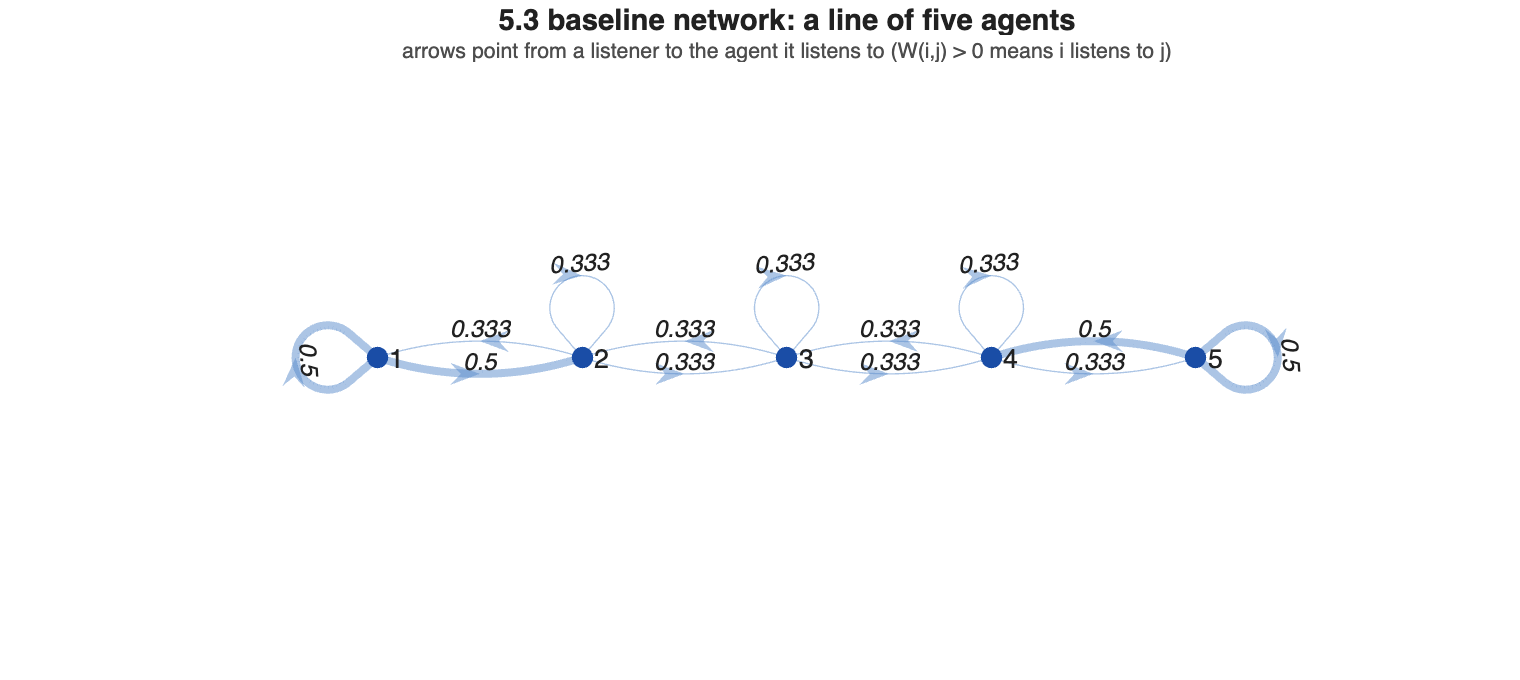


figure('Position',[0 0 760 340]);
plot_graph(W, [], 'Layout', [(1:5).' zeros(5,1)], ...
    'Title','5.3 baseline network: a line of five agents', ...
    'Subtitle','arrows point from a listener to the agent it listens to (W(i,j) > 0 means i listens to j)')

The parameters. The prejudices put the two ends of the line at opposite poles and leave the middle at zero - the configuration in which a cleavage, if there is one, is easiest to read. The initial opinions are deliberately unrelated to the prejudices, so that u = x(0) is never assumed by accident.

u  = [ 1;  0;  0;  0; -1];      % prejudices: the two ends pull in opposite directions
x0 = [ 0;  2; -2;  3;  1];      % initial opinions, unrelated to u on purpose
K  = 200;                       % simulation horizon, long enough for every case below

fprintf('u          = %s\n', mat2str(u.'));

u          = [1 0 0 0 -1]


fprintf('x(0)       = %s\n', mat2str(x0.'));

x(0)       = [0 2 -2 3 1]


fprintf('p''u        = %.6f   (zero here: the line and u are both symmetric end to end)\n', round(p.'*u, 12));

p'u        = -0.000000   (zero here: the line and u are both symmetric end to end)


fprintf('p''x(0)     = %.6f   (the French-DeGroot consensus this x(0) actually reaches)\n', p.'*x0);

p'x(0)     = 0.846154   (the French-DeGroot consensus this x(0) actually reaches)


Before any result, six checks that the implementation really is (M4.1) and that the analytical formulas are being applied only where they are licensed.

% 1. Lambda = I must reproduce French-DeGroot exactly.
d1 = max(abs(sim_degroot(W, x0, 40) - sim_friedkin_johnsen(W, ones(n,1), u, x0, 40)), [], 'all');

% 2. lambda_i = 0 must freeze agent i at u_i from step 1 onwards.
Xz = sim_friedkin_johnsen(W, [0; 1; 1; 1; 0], u, x0, 20);
d2 = max(abs(Xz([1 5], 2:end) - u([1 5])), [], 'all');

% 3. For homogeneous Lambda, rho(Lambda W) = lambda, since rho(W) = 1.
d3 = max(arrayfun(@(l) abs(max(abs(eig(l*W))) - l), 0:0.01:0.99));

% 4. Where the model is asymptotically stable, simulation must match x(inf) = V u.
lam0 = 0.8 * ones(n,1);
X4   = sim_friedkin_johnsen(W, lam0, u, x0, K);
d4   = max(abs(X4(:,end) - fj_equilibrium(W, lam0, u)));

% 5. V must be row-stochastic (Theorem 4.1), so the limit is a convex combination of the prejudices.
V  = total_influence(W, lam0);
d5 = max(abs(sum(V, 2) - 1));

fprintf('1. FJ with Lambda = I equals DeGroot        : %.2e\n', d1);

1. FJ with Lambda = I equals DeGroot        : 0.00e+00


fprintf('2. lambda_i = 0 gives x_i(k) = u_i, k >= 1  : %.2e\n', d2);

2. lambda_i = 0 gives x_i(k) = u_i, k >= 1  : 0.00e+00


fprintf('3. rho(lambda W) = lambda                   : %.2e\n', d3);

3. rho(lambda W) = lambda                   : 7.77e-16


fprintf('4. simulation equals fj_equilibrium         : %.2e\n', d4);

4. simulation equals fj_equilibrium         : 1.11e-16


fprintf('5. V row-stochastic                         : %.2e   (min entry %.4f)\n', d5, min(V(:)));

5. V row-stochastic                         : 4.44e-16   (min entry 0.0286)


fprintf('6. rank(limit_matrix(W)) = %d   vs   rank(V) = %d\n', rank(limit_matrix(W)), rank(V));

6. rank(limit_matrix(W)) = 1   vs   rank(V) = 5


Check 6 is not a check but the headline of Experiment 2, arriving early: the French-DeGroot limit operator has rank one, so the group can only agree; V has full rank, so every agent keeps a trace of its own prejudice.

One more precaution used throughout. fj_report(W, lambda) states the hypotheses of Theorem 4.1 and Corollaries 4.1-4.2 for a given configuration - who is prejudiced, who is P-dependent, rho(Lambda W), rho(Lambda11 W11), whether W22 is regular - so that x(inf) = V u is never applied to a model that does not satisfy the conditions for it.

fj_report(W, [0.5; 1; 1; 1; 1]);

prejudiced (lambda < 1) : 1
frozen     (lambda = 0) : (none)
P-dependent             : [1 2 3 4 5]   (5 of 5)
P-independent           : (none)
rho(Lambda W)           : 0.962763
rho(Lambda11 W11)       : 0.962763   < 1 always, by Theorem 4.1
asymptotically stable   : 1   (Corollary 4.1: all agents P-dependent)
convergent              : 1   (Corollary 4.2)


## 5.4 Experiment 1 - susceptibility

Fixed: W, u, x(0). Varied: Lambda only.

## 5.4.1 Homogeneous susceptibility, Lambda = lambda I

Here the algebra is completely explicit, which is why it is the right place to start. Lambda W = lambda W, so rho(Lambda W) = lambda * rho(W) = lambda exactly; and V_lambda = (1 - lambda)(I - lambda W)^-1 moves continuously from V_0 = I, where every agent sits frozen at its own prejudice, to V_1 = 1 p, which is French-DeGroot consensus at pu. So lambda moves the speed AND the destination, and the question is how they move relative to each other.

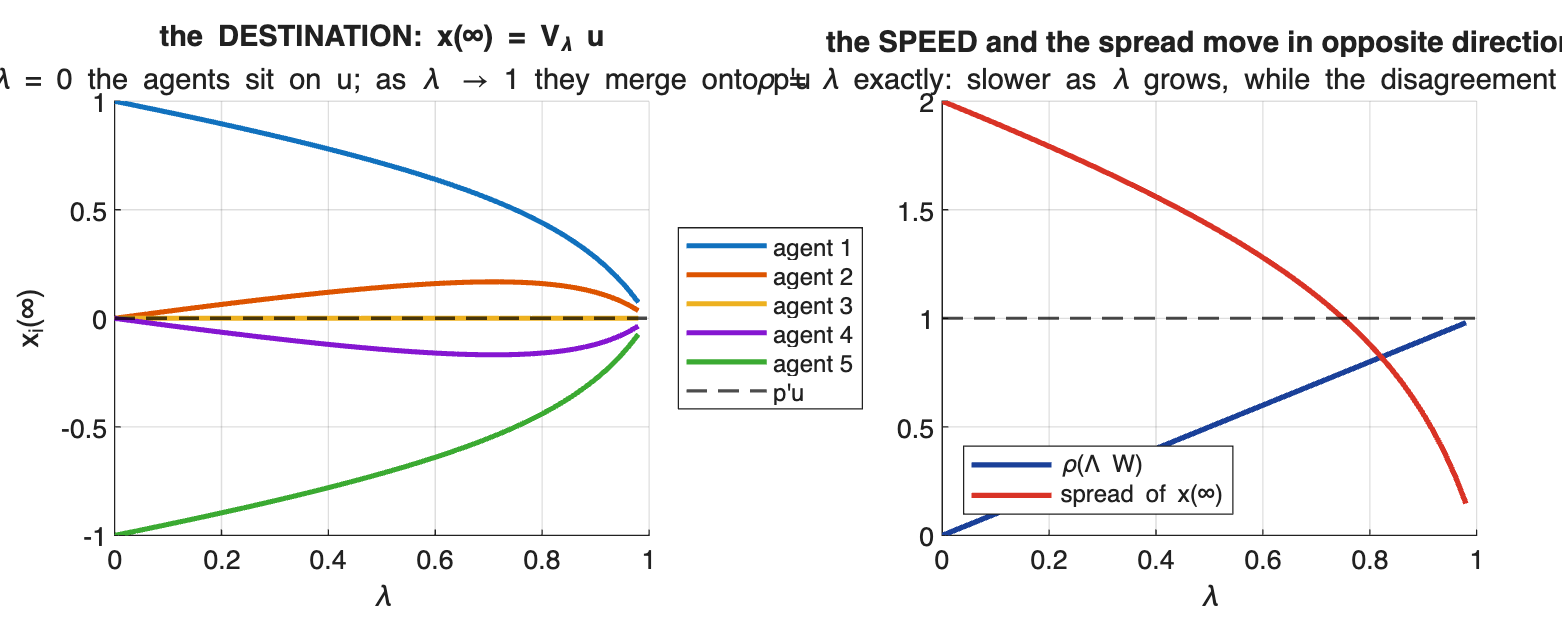

lams = 0:0.02:0.98;
Xinf = zeros(n, numel(lams));
rho  = zeros(1, numel(lams));
for j = 1:numel(lams)
    Xinf(:,j) = fj_equilibrium(W, lams(j)*ones(n,1), u);
    rho(j)    = max(abs(eig(lams(j)*W)));
end

figure('Position',[0 0 1150 460]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');

nexttile; hold on
co = lines(n);
for i = 1:n
    plot(lams, Xinf(i,:), 'LineWidth', 1.9, 'Color', co(i,:), ...
        'DisplayName', sprintf('agent %d', i));
end
yline(p.'*u, 'k--', 'LineWidth', 1.3, 'DisplayName','p''u');
grid on; legend('Location','eastoutside'); xlabel('\lambda'); ylabel('x_i(\infty)');
title('the DESTINATION: x(\infty) = V_\lambda u', 'FontWeight','bold');
subtitle('at \lambda = 0 the agents sit on u; as \lambda \rightarrow 1 they merge onto p''u');

nexttile; hold on
plot(lams, rho, 'LineWidth', 2, 'Color', [0.10 0.25 0.60], 'DisplayName','\rho(\Lambda W)');
plot(lams, max(Xinf,[],1) - min(Xinf,[],1), 'LineWidth', 2, ...
    'Color', [0.85 0.20 0.15], 'DisplayName','spread of x(\infty)');
yline(1, 'k--', 'LineWidth', 1.1, 'HandleVisibility','off');
grid on; legend('Location','southwest'); xlabel('\lambda');
title('the SPEED and the spread move in opposite directions', 'FontWeight','bold');
subtitle('\rho = \lambda exactly: slower as \lambda grows, while the disagreement shrinks');

The left panel also shows something the algebra does not advertise: agents 2 and 4 are NOT monotone in lambda. They first move away from zero, towards the pole nearer to them, peaking near lambda = 0.7, and only then get averaged back onto the consensus. Low susceptibility keeps them on their own prejudice of 0; high susceptibility merges them with everyone; in between, they are pulled by their neighbours before the pull becomes global. Worth checking whether this survives on other topologies.

The two curves in the right panel are the point of the experiment. The spectral radius rises linearly to 1, so the group settles ever more slowly; the spread of the equilibrium falls to 0, so it settles on ever closer opinions. Susceptibility buys agreement at the cost of speed, and at lambda = 1 it has bought complete agreement at the cost of never converging at all.

% The limiting statement, checked numerically: V_lambda u -> (p'u) 1 as lambda -> 1.
% A prejudice vector with p'u different from 0 is used, so the test is not degenerate.
ub = [1; 0.5; 0; 0; -0.2];
fprintf('p''ub = %.6f\n', p.'*ub);

p'ub = 0.238462


fprintf(' lambda      max|x(inf) - (p''ub)1|     spread\n');

 lambda      max|x(inf) - (p'ub)1|     spread


for l = [0.9 0.99 0.999 0.9999]
    xi = fj_equilibrium(W, l*ones(n,1), ub);
    fprintf(' %-8.4g    %.3e              %.3e\n', l, max(abs(xi - p.'*ub)), max(xi)-min(xi));
end

 0.9         2.413e-01              4.260e-01
 0.99        3.308e-02              6.009e-02
 0.999       3.441e-03              6.270e-03
 0.9999      3.455e-04              6.297e-04


The error falls by a factor of ten each time 1 - lambda does, which is the behaviour Lemma 4.1 describes: c_alpha tends to French social power as alpha tends to 1. Four representative trajectories now show the same statement as dynamics rather than as a limit.

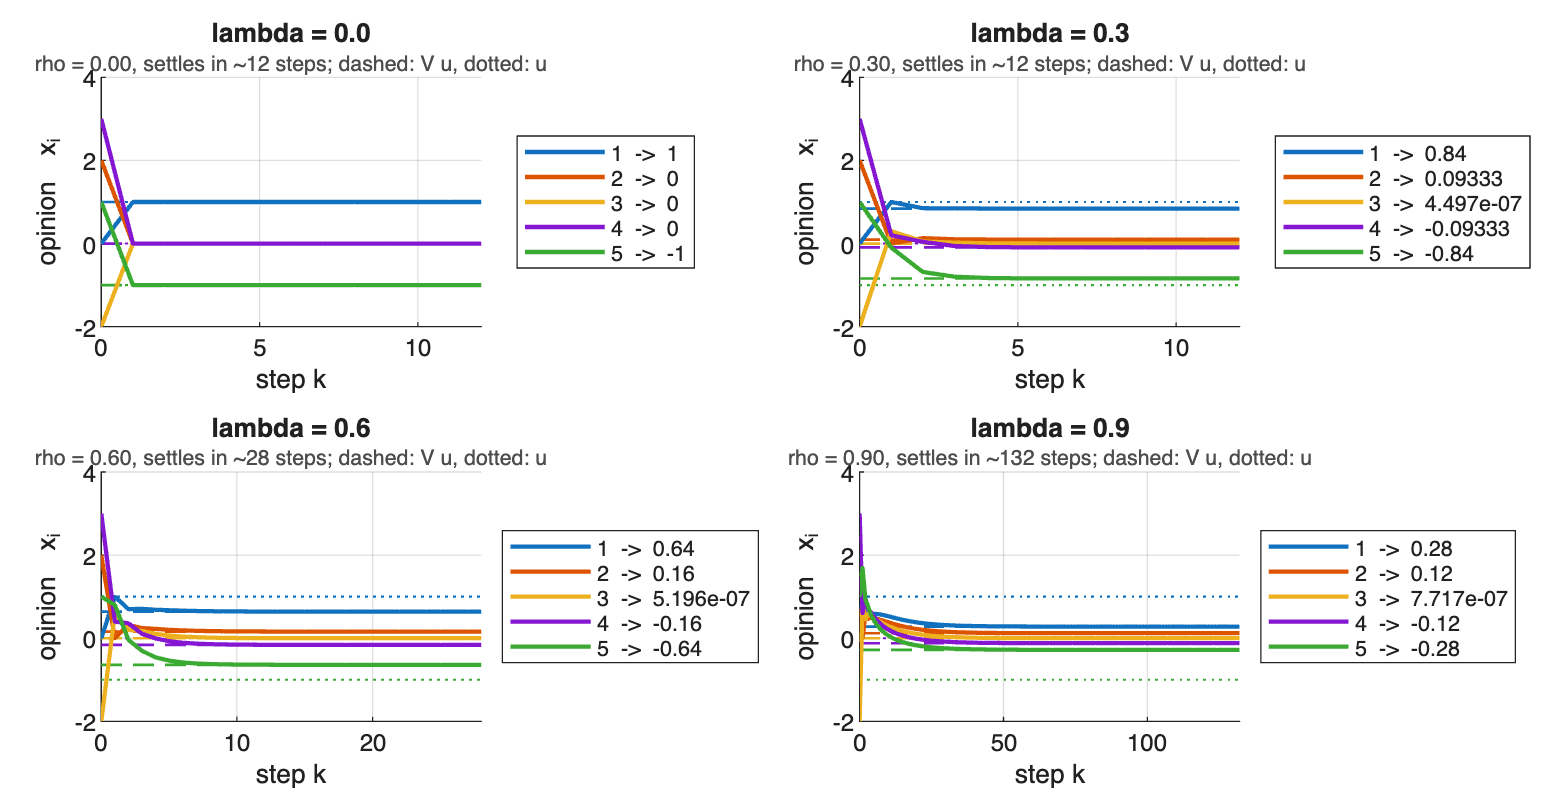

sel = [0 0.3 0.6 0.9];

figure('Position',[0 0 1250 640]);
tiledlayout(2, 2, 'TileSpacing','compact', 'Padding','compact');
for l = sel
    lam = l * ones(n,1);
    Kl  = max(12, min(300, ceil(log(1e-6)/log(max(l, 1e-3)))));
    X   = sim_friedkin_johnsen(W, lam, u, x0, Kl);
    nexttile;
    plot_opinions(X, [], 'Limit', fj_equilibrium(W, lam, u), 'Prejudice', u, ...
        'Title', sprintf('lambda = %.1f', l), ...
        'Subtitle', sprintf('rho = %.2f, settles in ~%d steps; dashed: V u, dotted: u', l, Kl));
end

## 5.4.2 Heterogeneous susceptibility, with the mean held fixed

The homogeneous case can leave the impression that lambda is a single group-level dial. It is not. The four configurations below all have mean(lambda) = 0.8 and differ only in how that susceptibility is distributed over the line.

cases = {'uniform, lambda_i = 0.8',      0.8*ones(n,1); ...
         'end agent 1 frozen',           [0; 1; 1; 1; 1]; ...
         'middle agent 3 frozen',        [1; 1; 0; 1; 1]; ...
         'both ends half-susceptible',   [0.5; 1; 1; 1; 0.5]};

fprintf('%-30s mean  rho     rank(V)  spread   x(inf)\n', 'configuration');

configuration                  mean  rho     rank(V)  spread   x(inf)


Xi = zeros(n, size(cases,1));
for c = 1:size(cases,1)
    lam = cases{c,2};
    r   = fj_report(W, lam);
    Xi(:,c) = fj_equilibrium(W, lam, u);
    fprintf('%-30s %.2f  %.4f  %d        %.4f   %s\n', cases{c,1}, mean(lam), r.rho, ...
        rank(total_influence(W, lam)), max(Xi(:,c))-min(Xi(:,c)), mat2str(round(Xi(:,c).', 3)));
end

uniform, lambda_i = 0.8        0.80  0.8000  5        0.8800   [0.44 0.16 0 -0.16 -0.44]
end agent 1 frozen             0.80  0.9532  1        0.0000   [1 1 1 1 1]
middle agent 3 frozen          0.80  0.8333  1        0.0000   [0 0 0 0 0]
both ends half-susceptible     0.80  0.8760  2        1.6000   [0.8 0.4 0 -0.4 -0.8]


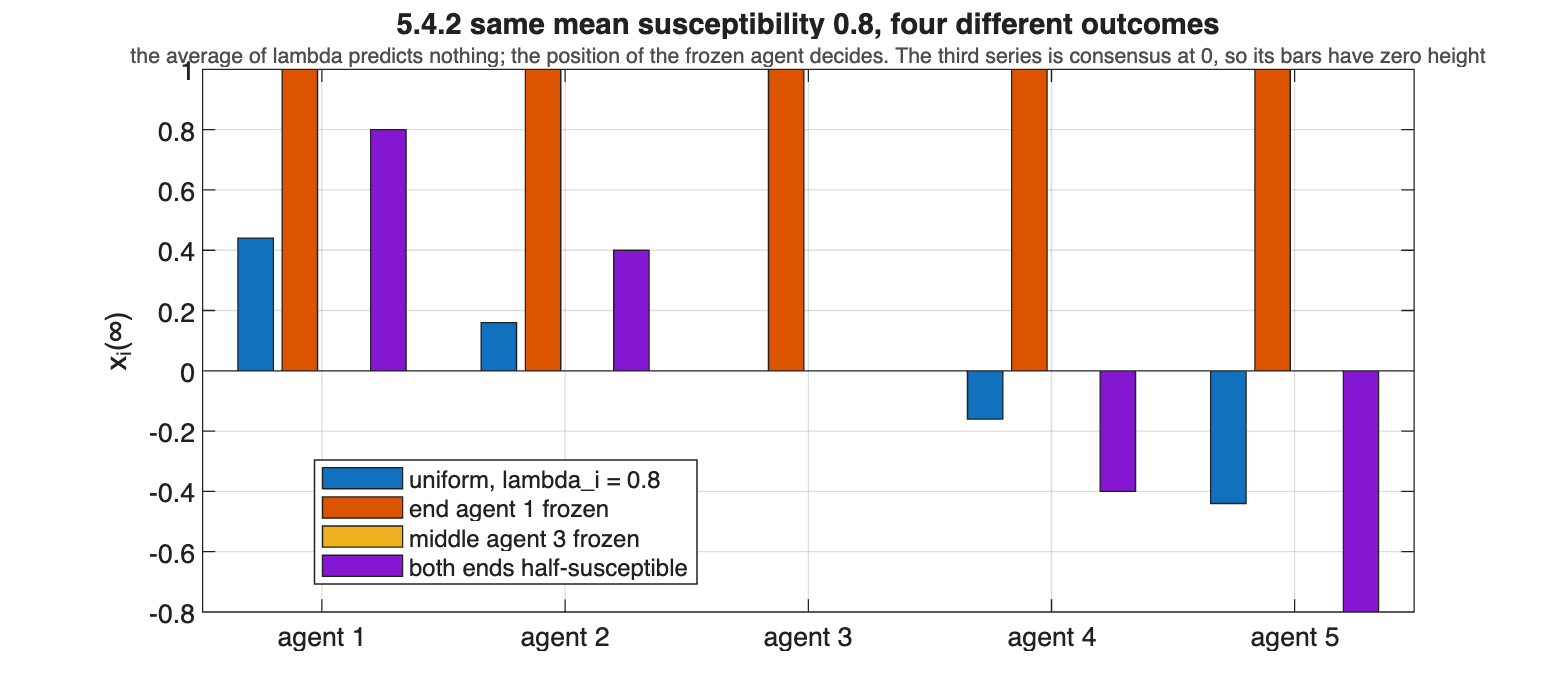


figure('Position',[0 0 1000 440]);
plot_bars(Xi, compose('agent %d', 1:n), 'Series', cases(:,1).', ...
    'YLabel','x_i(\infty)', 'Values', false, ...
    'Title','5.4.2 same mean susceptibility 0.8, four different outcomes', ...
    'Subtitle','the average of lambda predicts nothing; the position of the frozen agent decides. The third series is consensus at 0, so its bars have zero height')

Same W, same u, same x(0), same mean susceptibility - and the outcomes are, in the order of the table: a gradient of spread 0.88, a consensus at +1, a consensus at 0, and a gradient of spread 1.6. The average susceptibility is not a sufficient statistic; the identity of the anchored agents is. The rank column already anticipates Experiment 3: it equals the number of prejudiced agents in every row.

## 5.5 Experiment 2 - Friedkin-Johnsen against French-DeGroot

Fixed: W. Compared: x(k+1) = W x(k) against x(k+1) = Lambda W x(k) + (I - Lambda)u, with lambda_i = 0.8 for every agent, so that no agent is frozen and the only difference is the prejudice term.

Note that on this network French-DeGroot DOES converge - the graph is rooted and aperiodic - so the comparison is not won for free. Both models settle; the question is on what, and why.

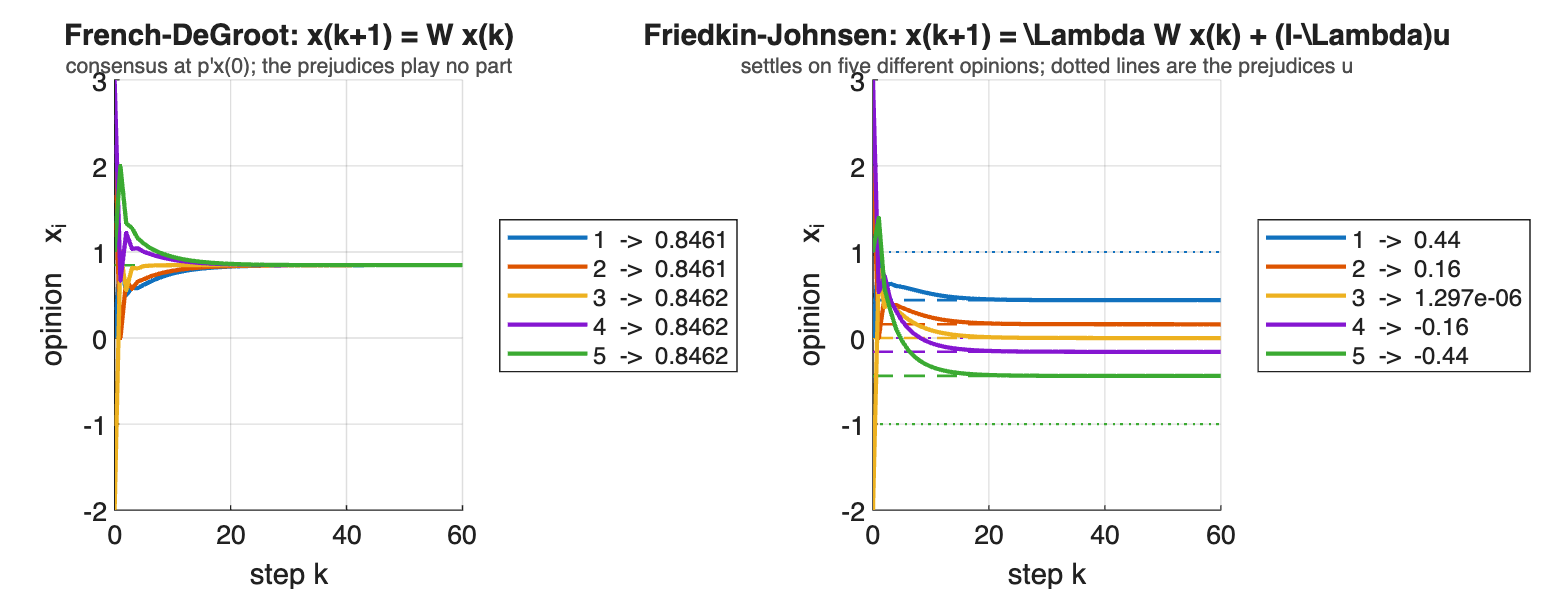

lam = 0.8 * ones(n,1);
Xd  = sim_degroot(W, x0, 60);
Xf  = sim_friedkin_johnsen(W, lam, u, x0, 60);

figure('Position',[0 0 1150 440]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
nexttile;
plot_opinions(Xd, [], 'Limit', limit_matrix(W)*x0, ...
    'Title','French-DeGroot: x(k+1) = W x(k)', ...
    'Subtitle','consensus at p''x(0); the prejudices play no part');
nexttile;
plot_opinions(Xf, [], 'Limit', fj_equilibrium(W, lam, u), 'Prejudice', u, ...
    'Title','Friedkin-Johnsen: x(k+1) = \Lambda W x(k) + (I-\Lambda)u', ...
    'Subtitle','settles on five different opinions; dotted lines are the prejudices u');

Three differences, each of which is a number rather than an impression.

% (a) the initial condition. Same u, three different x(0).
fprintf('(a) does the model forget x(0)?\n');

(a) does the model forget x(0)?


for x = {x0, [10;10;10;10;10], [-5;5;-5;5;-5]}
    Ld = sim_degroot(W, x{1}, 400);
    Lf = sim_friedkin_johnsen(W, lam, u, x{1}, 400);
    fprintf('    x(0) = %-20s  DeGroot -> %7.4f (all)   FJ -> %s\n', ...
        mat2str(x{1}.'), Ld(1,end), mat2str(round(Lf(:,end).', 4)));
end

    x(0) = [0 2 -2 3 1]          DeGroot ->  0.8462 (all)   FJ -> [0.44 0.16 0 -0.16 -0.44]
    x(0) = [10 10 10 10 10]      DeGroot -> 10.0000 (all)   FJ -> [0.44 0.16 0 -0.16 -0.44]
    x(0) = [-5 5 -5 5 -5]        DeGroot -> -0.3846 (all)   FJ -> [0.44 0.16 0 -0.16 -0.44]



% (b) the prejudices. Same x(0), three different u.
fprintf('\n(b) does the model respond to u?\n');


(b) does the model respond to u?


for uu = {u, [2;0;0;0;-2], [0;0;0;0;0]}
    Lf = sim_friedkin_johnsen(W, lam, uu{1}, x0, 400);
    fprintf('    u    = %-20s  DeGroot -> unchanged      FJ -> %s\n', ...
        mat2str(uu{1}.'), mat2str(round(Lf(:,end).', 4)));
end

    u    = [1 0 0 0 -1]          DeGroot -> unchanged      FJ -> [0.44 0.16 0 -0.16 -0.44]
    u    = [2 0 0 0 -2]          DeGroot -> unchanged      FJ -> [0.88 0.32 0 -0.32 -0.88]
    u    = [0 0 0 0 0]           DeGroot -> unchanged      FJ -> [0 0 0 0 0]


French-DeGroot remembers only x(0) and cannot see u at all; Friedkin-Johnsen remembers only u and has forgotten x(0) entirely. The third difference is structural, and explains the other two.

Winf = limit_matrix(W)

Winf =     0.1538    0.2308    0.2308    0.2308    0.1538
    0.1538    0.2308    0.2308    0.2308    0.1538
    0.1538    0.2308    0.2308    0.2308    0.1538
    0.1538    0.2308    0.2308    0.2308    0.1538
    0.1538    0.2308    0.2308    0.2308    0.1538


V    = total_influence(W, lam)

V =     0.4686    0.3044    0.1341    0.0644    0.0286
    0.2029    0.4565    0.2011    0.0965    0.0429
    0.0894    0.2011    0.4190    0.2011    0.0894
    0.0429    0.0965    0.2011    0.4565    0.2029
    0.0286    0.0644    0.1341    0.3044    0.4686



fprintf('rank(W^inf) = %d  -> the limit is 1 * (p''x(0)): one number, the same for everyone\n', rank(Winf));

rank(W^inf) = 1  -> the limit is 1 * (p'x(0)): one number, the same for everyone


fprintf('rank(V)     = %d  -> the limit is V u: n numbers, one per agent\n', rank(V));

rank(V)     = 5  -> the limit is V u: n numbers, one per agent


fprintf('both are row-stochastic: max|row sum - 1| = %.2e and %.2e\n', ...
    max(abs(sum(Winf,2)-1)), max(abs(sum(V,2)-1)));

both are row-stochastic: max|row sum - 1| = 1.11e-16 and 4.44e-16


Both limit operators are row-stochastic, so in both models the final opinions lie inside the convex hull of what is fed in - disagreement is bounded, never runaway. What separates them is the RANK. W^inf = 1 p collapses the whole state onto one direction, which is why averaging can only ever produce agreement. V has full rank, so the map from prejudices to final opinions is invertible: persistent, structured disagreement, from a network that is fully connected and in which everybody keeps talking to everybody.

## 5.6 Experiment 3 - one prejudiced agent against several

Fixed: W, u, x(0), and the value lambda_i = 0.5 for whoever is prejudiced. Varied: the SET of prejudiced agents.

There is an exact prediction to test. (I - Lambda) has one non-zero row per prejudiced agent, so its rank is the number of prejudiced agents; and where the model is asymptotically stable (I - Lambda W)^-1 is invertible, so V = (I - Lambda W)^-1 (I - Lambda) has exactly that same rank. The number of anchors is therefore the dimension of the space of achievable equilibria.

sets = {1, 3, [1 5], [1 3 5], 1:5};

fprintf('%-18s %-8s %-8s %-8s %s\n', 'prejudiced', 'rho', 'rank(V)', 'spread', 'x(inf)');

prejudiced         rho      rank(V)  spread   x(inf)


for s = 1:numel(sets)
    lam = ones(n,1);  lam(sets{s}) = 0.5;
    r   = fj_report(W, lam);
    Vs  = total_influence(W, lam);
    xi  = Vs * u;
    fprintf('%-18s %-8.4f %-8d %-8.4f %s\n', mat2str(sets{s}), r.rho, rank(Vs), ...
        max(xi)-min(xi), mat2str(round(xi.', 4)));
end

1                  0.9628   1        0.0000   [1 1 1 1 1]
3                  0.9007   1        0.0000   [0 0 0 0 0]
[1 5]              0.8760   2        1.6000   [0.8 0.4 0 -0.4 -0.8]
[1 3 5]            0.7151   3        1.6000   [0.8 0.4 0 -0.4 -0.8]
[1 2 3 4 5]        0.5000   5        1.4286   [0.7143 0.1429 0 -0.1429 -0.7143]


fprintf('\nLambda = I (no prejudiced agent): rho(Lambda W) = %.4f, V does not exist.\n', ...
    max(abs(eig(W))));


Lambda = I (no prejudiced agent): rho(Lambda W) = 1.0000, V does not exist.


rank(V) is the number of prejudiced agents in every row, exactly as predicted. The two rows that matter most are the first and the third.

% ONE prejudiced agent, on a strongly connected graph.
lam1 = ones(n,1);  lam1(1) = 0.5;
V1   = total_influence(W, lam1)

V1 =     1.0000         0         0         0         0
    1.0000         0         0         0         0
    1.0000         0         0         0         0
    1.0000         0         0         0         0
    1.0000         0         0         0         0



fprintf('V1 has one non-zero column and is row-stochastic, so V1 = 1 * e_1'':  max|V1 - 1 e_1''| = %.2e\n', ...
    max(abs(V1 - ones(n,1)*[1 0 0 0 0]), [], 'all'));

V1 has one non-zero column and is row-stochastic, so V1 = 1 * e_1':  max|V1 - 1 e_1'| = 2.00e-15


fprintf('  -> every agent converges to u_1 = %g. One anchor still gives CONSENSUS.\n', u(1));

  -> every agent converges to u_1 = 1. One anchor still gives CONSENSUS.



% TWO prejudiced agents, at the two ends of the line.
lam2 = ones(n,1);  lam2([1 5]) = 0.5;
V2   = total_influence(W, lam2)

V2 =     0.9000         0         0         0    0.1000
    0.7000         0         0         0    0.3000
    0.5000         0         0         0    0.5000
    0.3000         0         0         0    0.7000
    0.1000         0         0         0    0.9000



fprintf('V2 has two non-zero columns; each row is a convex combination of u_1 and u_5.\n');

V2 has two non-zero columns; each row is a convex combination of u_1 and u_5.


fprintf('  -> x(inf) = %s : a linear gradient along the line. CLEAVAGE.\n', ...
    mat2str(round((V2*u).', 4)));

  -> x(inf) = [0.8 0.4 0 -0.4 -0.8] : a linear gradient along the line. CLEAVAGE.


This is the sharpest result in the notebook. A single prejudiced agent in a strongly connected network does not produce disagreement at all - it produces consensus, at its own prejudice, because V collapses to 1 e_1. What a single anchor changes is WHICH consensus: French-DeGroot would have given px(0), a weighted average of where everyone started, whereas here the whole group ends on u_1 and the initial opinions are erased. Persistent disagreement needs at least two anchors holding DIFFERENT prejudices.

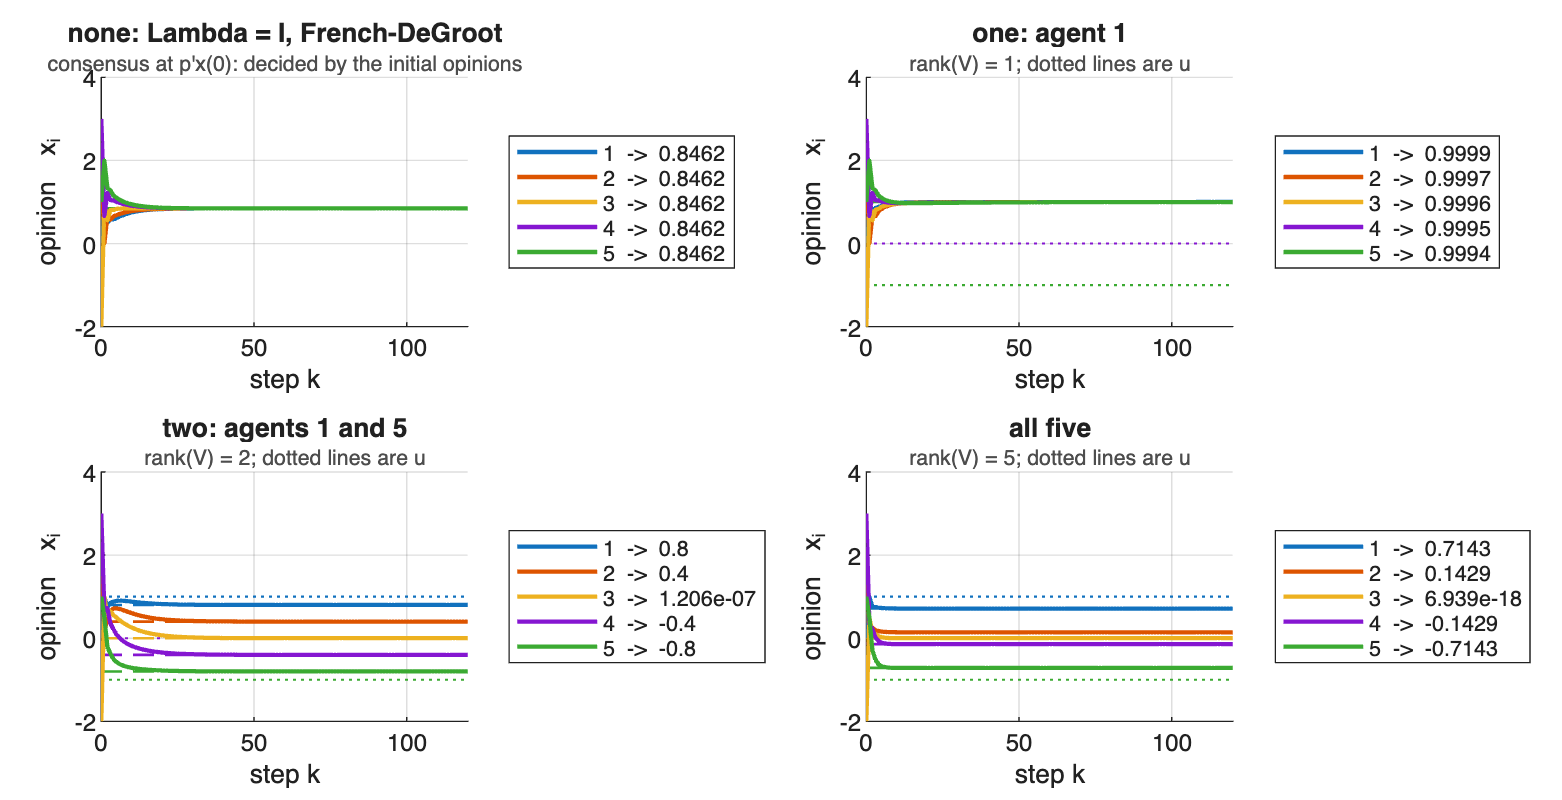

figure('Position',[0 0 1250 640]);
tiledlayout(2, 2, 'TileSpacing','compact', 'Padding','compact');
show = {[],  1,  [1 5],  1:5};
name = {'none: Lambda = I, French-DeGroot', 'one: agent 1', 'two: agents 1 and 5', 'all five'};
for s = 1:4
    lam = ones(n,1);
    if ~isempty(show{s}), lam(show{s}) = 0.5; end
    X = sim_friedkin_johnsen(W, lam, u, x0, 120);
    nexttile;
    if isempty(show{s})
        plot_opinions(X, [], 'Limit', limit_matrix(W)*x0, 'Title', name{s}, ...
            'Subtitle','consensus at p''x(0): decided by the initial opinions');
    else
        plot_opinions(X, [], 'Limit', fj_equilibrium(W, lam, u), 'Prejudice', u, ...
            'Title', name{s}, 'Subtitle', sprintf('rank(V) = %d; dotted lines are u', numel(show{s})));
    end
end

One further observation worth keeping: the row for the set [1 3 5] has the same equilibrium as the row for [1 5], because u_3 = 0 is exactly where agent 3 was already going to end up. Anchoring an agent at the opinion it would have held anyway changes rho - the group settles faster - without moving the equilibrium at all.

## 5.7 Experiment 4 - network topology

Lambda and u are now frozen and only the graph changes. The design keeps the comparison as controlled as it can be made: two triangles, each internally complete and with self-loops, joined by exactly ONE bridge edge, and only the DIRECTION of that bridge varies. Agents 1 and 2 are the prejudiced ones, both in the left triangle, with opposite prejudices.

The convention decides how this reads, so it is worth stating again. W(i,j) > 0 means i listens to j, and a prejudice travels ALONG the arrows: agent i is P-dependent when a walk i -> ... -> j reaches a prejudiced j. Part I draws the arrows the other way and phrases the same condition as "a walk from j to i exists". The matrices are identical; only the pictures differ.

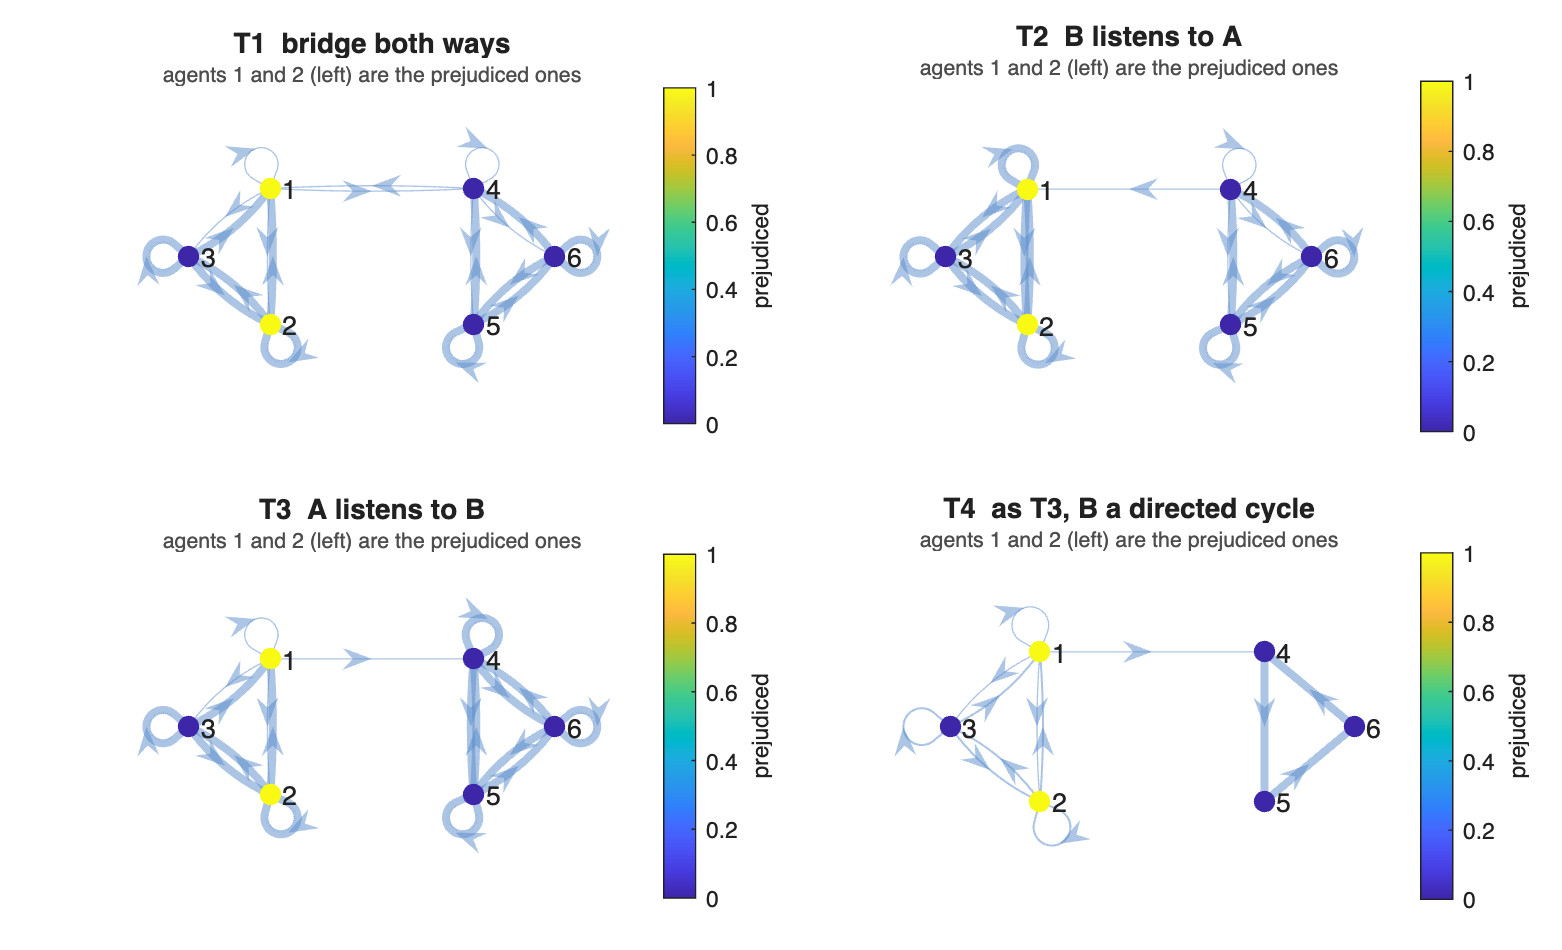

base = zeros(6);
base(1,[1 2 3]) = 1;  base(2,[1 2 3]) = 1;  base(3,[1 2 3]) = 1;   % group A: 1,2,3
base(4,[4 5 6]) = 1;  base(5,[4 5 6]) = 1;  base(6,[4 5 6]) = 1;   % group B: 4,5,6

G1 = base;  G1(4,1) = 1;  G1(1,4) = 1;      % bridge both ways
G2 = base;  G2(4,1) = 1;                    % B listens to A   (4 listens to 1)
G3 = base;  G3(1,4) = 1;                    % A listens to B   (1 listens to 4)

G4 = zeros(6);                              % as G3, but B is a directed 3-cycle
G4(1,[1 2 3]) = 1;  G4(2,[1 2 3]) = 1;  G4(3,[1 2 3]) = 1;
G4(4,5) = 1;  G4(5,6) = 1;  G4(6,4) = 1;  G4(1,4) = 1;

topo = {'T1  bridge both ways',        row_stochastic(G1); ...
        'T2  B listens to A',          row_stochastic(G2); ...
        'T3  A listens to B',          row_stochastic(G3); ...
        'T4  as T3, B a directed cycle', row_stochastic(G4)};

lamT = [0.5; 0.5; 1; 1; 1; 1];              % agents 1 and 2 prejudiced, both in group A
uT   = [  1;  -1; 0; 0; 0; 0];              % and pulling in opposite directions
x0T  = [  0;   0; 0; 6; 4; 2];              % group B starts far from A, and spread out

posT = [0 1; 0 -1; -1.2 0; 3 1; 3 -1; 4.2 0];
figure('Position',[0 0 1250 760]);
tiledlayout(2, 2, 'TileSpacing','compact', 'Padding','compact');
for k = 1:4
    nexttile;
    plot_graph(topo{k,2}, [], 'Layout', posT, 'Weights', false, ...
        'NodeValue', double(lamT < 1), 'NodeName','prejudiced', ...
        'Title', topo{k,1}, 'Subtitle','agents 1 and 2 (left) are the prejudiced ones');
end

The hypotheses first, for all four, before any trajectory is plotted.

for k = 1:4
    fprintf('--- %s\n', topo{k,1});
    fj_report(topo{k,2}, lamT);
    fprintf('\n');
end

--- T1  bridge both ways


prejudiced (lambda < 1) : [1 2]
frozen     (lambda = 0) : (none)
P-dependent             : [1 2 3 4 5 6]   (6 of 6)
P-independent           : (none)
rho(Lambda W)           : 0.930081
rho(Lambda11 W11)       : 0.930081   < 1 always, by Theorem 4.1
asymptotically stable   : 1   (Corollary 4.1: all agents P-dependent)
convergent              : 1   (Corollary 4.2)


--- T2  B listens to A


prejudiced (lambda < 1) : [1 2]
frozen     (lambda = 0) : (none)
P-dependent             : [1 2 3 4 5 6]   (6 of 6)
P-independent           : (none)
rho(Lambda W)           : 0.916667
rho(Lambda11 W11)       : 0.916667   < 1 always, by Theorem 4.1
asymptotically stable   : 1   (Corollary 4.1: all agents P-dependent)
convergent              : 1   (Corollary 4.2)


--- T3  A listens to B


prejudiced (lambda < 1) : [1 2]
frozen     (lambda = 0) : (none)
P-dependent             : [1 2 3]   (3 of 6)
P-independent           : [4 5 6]
rho(Lambda W)           : 1.000000
rho(Lambda11 W11)       : 0.625000   < 1 always, by Theorem 4.1
W22 regular             : 1
asymptotically stable   : 0   (Corollary 4.1: all agents P-dependent)
convergent              : 1   (Corollary 4.2)
  -> x(inf) = V u does NOT apply; the limit depends on x(0).


--- T4  as T3, B a directed cycle


prejudiced (lambda < 1) : [1 2]
frozen     (lambda = 0) : (none)
P-dependent             : [1 2 3]   (3 of 6)
P-independent           : [4 5 6]
rho(Lambda W)           : 1.000000
rho(Lambda11 W11)       : 0.625000   < 1 always, by Theorem 4.1
W22 regular             : 0
asymptotically stable   : 0   (Corollary 4.1: all agents P-dependent)
convergent              : 0   (Corollary 4.2)
  -> x(inf) = V u does NOT apply; the limit depends on x(0).


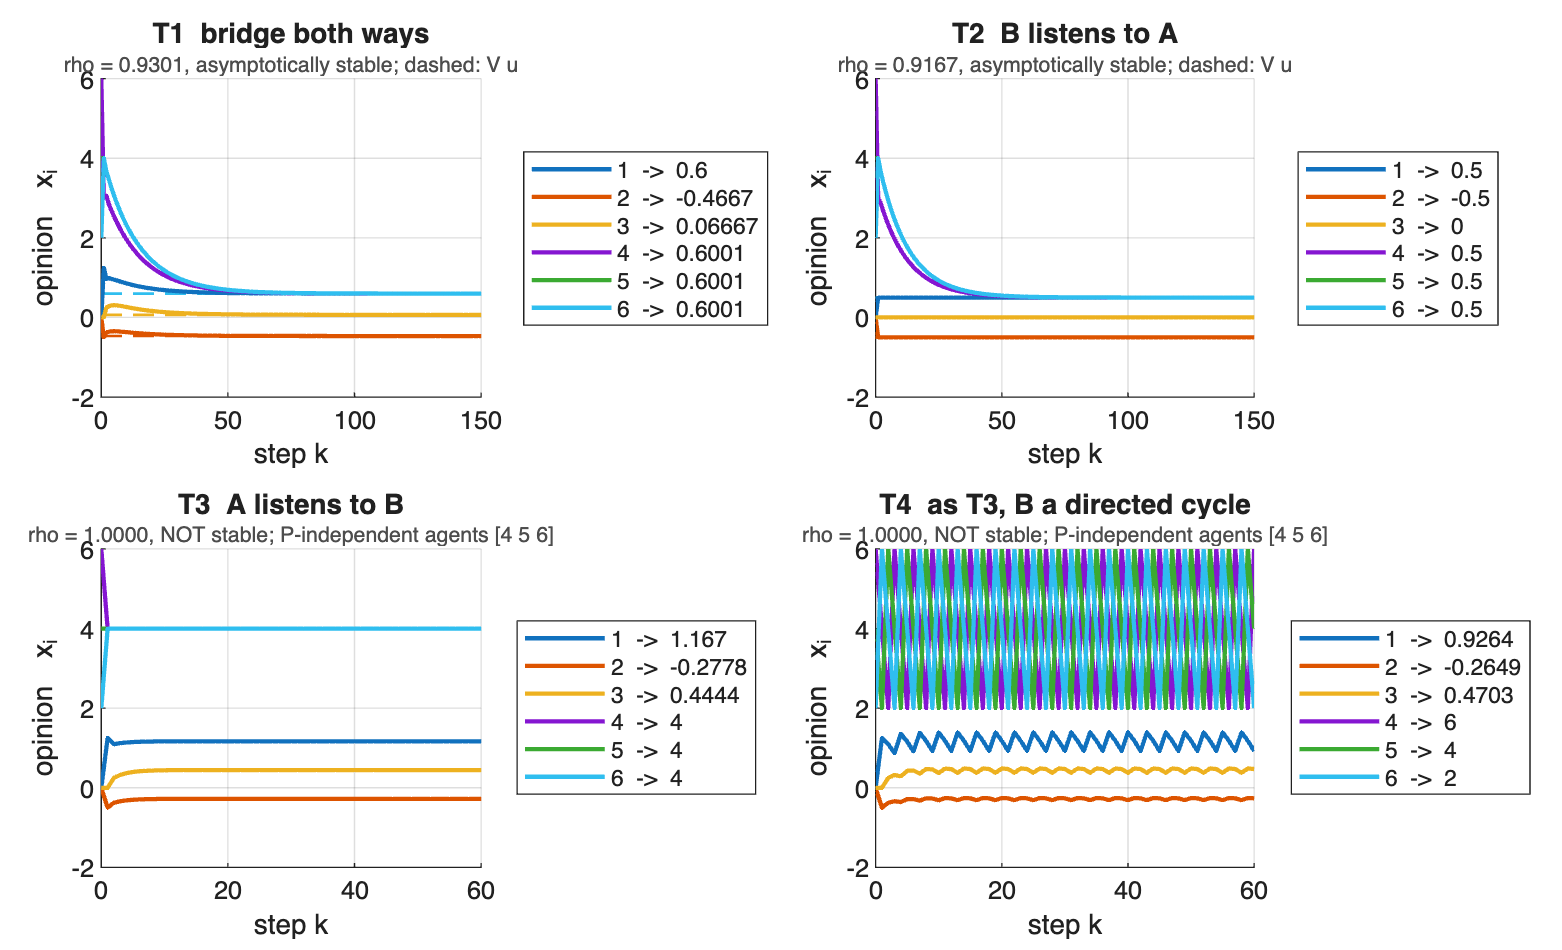

T1  bridge both ways             stable 1 | convergent 1 | settled 1 | same limit from a second x(0) 1
T2  B listens to A               stable 1 | convergent 1 | settled 1 | same limit from a second x(0) 1
T3  A listens to B               stable 0 | convergent 1 | settled 1 | same limit from a second x(0) 0
T4  as T3, B a directed cycle    stable 0 | convergent 0 | settled 0 | same limit from a second x(0) 0


figure('Position',[0 0 1250 760]);
tiledlayout(2, 2, 'TileSpacing','compact', 'Padding','compact');
for k = 1:4
    Wk = topo{k,2};
    r  = fj_report(Wk, lamT);
    X  = sim_friedkin_johnsen(Wk, lamT, uT, x0T, 400);
    X2 = sim_friedkin_johnsen(Wk, lamT, uT, x0T - [0;0;0;8;8;8], 400);
    nexttile;
    % The stable topologies are slow (rho ~ 0.92), so they need ~150 steps before
    % the legend's final value IS the limit; the unstable ones are plotted over 60
    % steps instead, which is where T4's period-3 rotation stays readable.
    if r.stable, Kshow = 150; else, Kshow = 60; end
    Xshow = X(:, 1:Kshow+1);
    if r.stable
        plot_opinions(Xshow, [], 'Limit', fj_equilibrium(Wk, lamT, uT), ...
            'Title', topo{k,1}, ...
            'Subtitle', sprintf('rho = %.4f, asymptotically stable; dashed: V u', r.rho));
    else
        plot_opinions(Xshow, [], 'Title', topo{k,1}, 'Subtitle', sprintf( ...
            'rho = %.4f, NOT stable; P-independent agents %s', r.rho, mat2str(find(~r.pdependent).')));
    end
    fprintf('%-32s stable %d | convergent %d | settled %d | same limit from a second x(0) %d\n', ...
        topo{k,1}, r.stable, r.convergent, ...
        max(abs(X(:,end)-X(:,end-1))) < 1e-9, max(abs(X(:,end)-X2(:,end))) < 1e-6);
end

Four topologies, four different theorems doing the work.

- T1, strongly connected: Corollary 4.1 applies directly, so the model is asymptotically stable and the limit is V u, independent of x(0). Group B settles between the two anchors.

- T2, the bridge pointing so that B listens to A: B is still reached by the prejudices, so every agent is P-dependent and the model is still asymptotically stable - strong connectivity is sufficient but not necessary. The equilibrium is different from T1, because reversing the information flow changes the weights in V.

- T3, the same single edge reversed: now nobody in B listens to anybody in A, so B is P-independent. rho(Lambda W) = 1 and V does not exist, while rho(Lambda11 W11) is still below 1 - which is exactly Theorem 4.1, the P-dependent block being stable whatever the rest does. B runs a French-DeGroot model of its own, reaches its own consensus, and DRAGS group A: the prejudices have lost control, and x(0) is back in the answer.

- T4, the same again with B made periodic: W22 is a directed 3-cycle, not regular, so by Corollary 4.2 the model does not converge at all. B rotates forever and A never settles either.

One edge, reversed, moves the system from "the prejudices decide everything and the past is forgotten" to "the past decides everything and the prejudices are dragged along". That is the whole content of the P-dependent / P-independent split, in a single controlled comparison.

## 5.8 Preliminary observations

What the four experiments produced, stated as claims that the numbers above support. These are for discussion, not conclusions.

- E1. For homogeneous Lambda, rho(Lambda W) = lambda exactly, and V_lambda interpolates between V_0 = I and V_1 = 1 p. So lambda controls the speed and the destination together, in opposite directions: more susceptibility means more agreement and slower convergence, with lambda = 1 the degenerate endpoint where agreement is total and convergence is lost.

- E1. With the mean susceptibility held fixed at 0.8, four distributions of it gave four different outcomes, from consensus at +1 to a gradient of spread 1.6. The average of lambda is not a sufficient statistic for the outcome.

- E2. On a network where French-DeGroot converges perfectly well, the two models still differ completely: DeGroot remembers x(0) and cannot see u; FJ remembers u and has forgotten x(0). The structural reason is the rank - rank(W^inf) = 1 against rank(V) = n - and both limit operators being row-stochastic is what keeps the disagreement bounded.

- E3. rank(V) equals the number of prejudiced agents, exactly. One prejudiced agent on a strongly connected graph still gives CONSENSUS, at that agents prejudice, since V = 1 e_1. Persistent disagreement requires at least two anchors with different prejudices.

- E4. With Lambda and u fixed, reversing a single bridge edge decides whether the prejudices reach the far half of the network. That single bit is the difference between asymptotic stability with x(inf) = V u, and rho(Lambda W) = 1 with a limit that depends on x(0) - or, if the unreached block happens to be periodic, no limit at all.

What is deliberately NOT tested here, and would be the natural next steps: the influence centrality c = n^-1 V 1 and its relation to French social power and PageRank (Chapter 4 already covers this analytically); the sensitivity of the equilibrium to u as a matrix question rather than a few samples; the multidimensional model of Parsegov et al.; and the gossip version of Part II, where the opinions stop converging pointwise and only their time averages reproduce x(inf).

Open points to settle before any of this is worth keeping: whether the line of five is the right baseline or whether the measured Friedkin-Johnsen 1999 network should be used instead; whether Experiment 1 and Experiment 3 overlap too much, since both end up describing V; and whether Experiment 4 needs T4 at all, given that Chapter 4 already makes the regularity point.